# PART-C

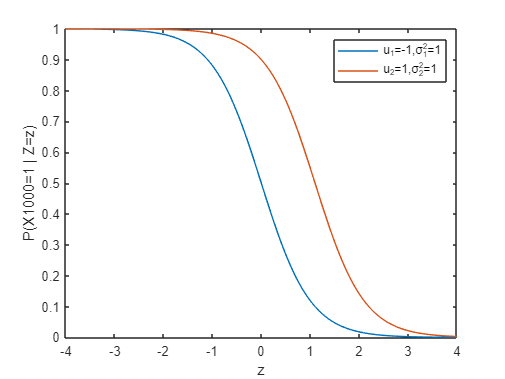

close all;
x=-4:0.01:4;

Gaussian_n_1 = makedist('Normal',  mu=-1 , sigma=sqrt(1));
Gaussian_n_2 = makedist('Normal',  mu=1  , sigma=sqrt(1));

f1=Gaussian_n_1.pdf(x);
f2=Gaussian_n_2.pdf(x);

theta = 0.5; gama = 0.5;
y=(f1.*(gama/(theta+gama)))./(f1.*gama+f2.*theta);

plot(x,y);
hold on;

theta = 0.1; gama = 0.9;
y=(f1.*(gama/(theta+gama)))./(f1.*gama+f2.*theta);

plot(x,y);

xlabel("z");
ylabel("P(X1000=1 | Z=z)")
legend('u_1=-1,σ_1^2=1','u_2=1,σ_2^2=1')

## PART-D

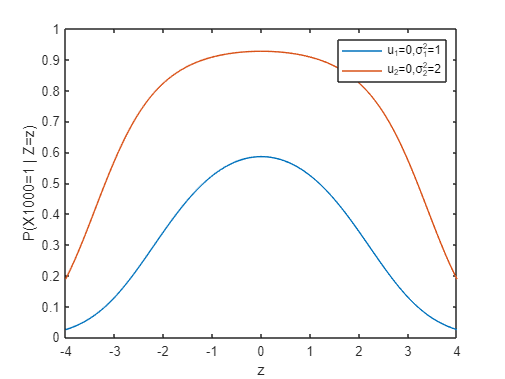

close all;
Gaussian_n_3 = makedist('Normal',  mu=0 , sigma=sqrt(1));
Gaussian_n_4 = makedist('Normal',  mu=0 , sigma=sqrt(2));

f3=Gaussian_n_3.pdf(x);
f4=Gaussian_n_4.pdf(x);

theta = 0.5; gama = 0.5;
y=(f3.*(gama/(theta+gama)))./(f3.*gama+f4.*theta);

plot(x,y);
hold on;

theta = 0.1; gama = 0.9;
y=(f3.*(gama/(theta+gama)))./(f3.*gama+f4.*theta);

plot(x,y);

xlabel("z");
ylabel("P(X1000=1 | Z=z)")
legend('u_1=0,σ_1^2=1','u_2=0,σ_2^2=2')